# ECE311:Solid State Electronic Devices

## Name: Omar Abdelfattah Shehatta Ibrahim

## ID: 1803343

## `Assignment(5)`

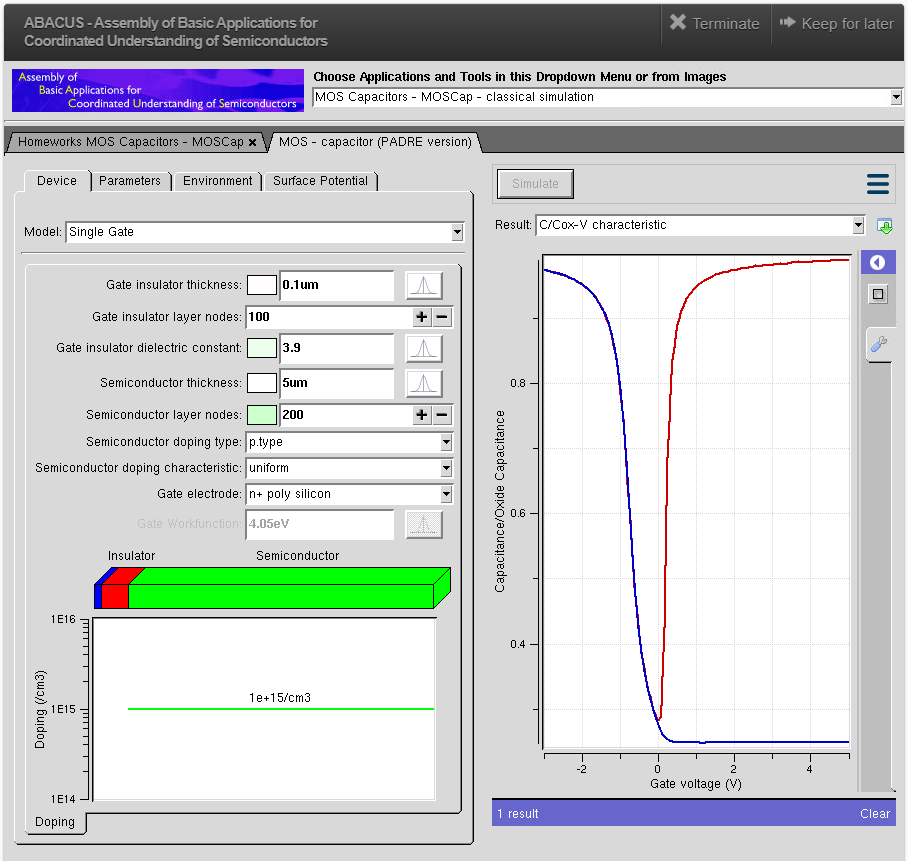

## `Assignment(6)`

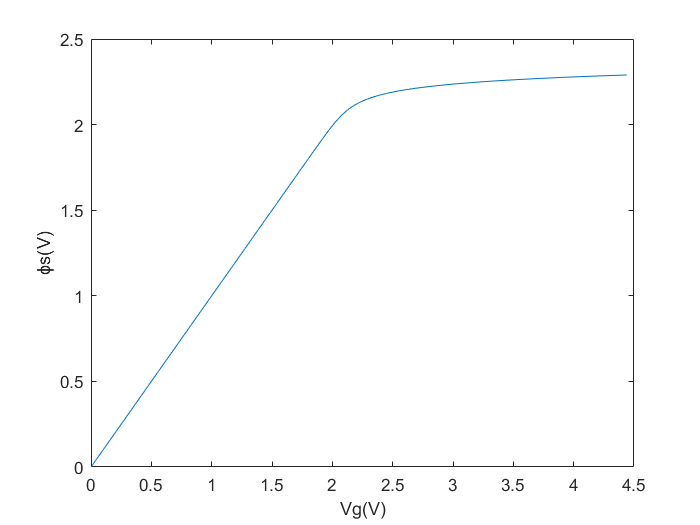

phi = -0.1:0.001:2.29;
ni = 1e10;
Na = 1e15;
ei = 3.9e9/(36*pi);
q = 1.60218e-19;
K = 1.38e-23;
T = 300;
V = K*T/q;
X = sqrt(2*ei*K*T*Na);
Qs1 = X*sqrt(exp(-phi/V)+phi/V-1 + ni^2/Na^2*(exp(phi/V)-phi/V-1));

phip = phi(phi>0);
tox  = 25e-9;
Cox = ei/tox;
Vg = phip +Qs1(end-length(phip)+1:end)/Cox;
plot(Vg,phip);
xlabel('Vg(V)');
ylabel(char(981)+"s(V)");

## `Assignment(7)`

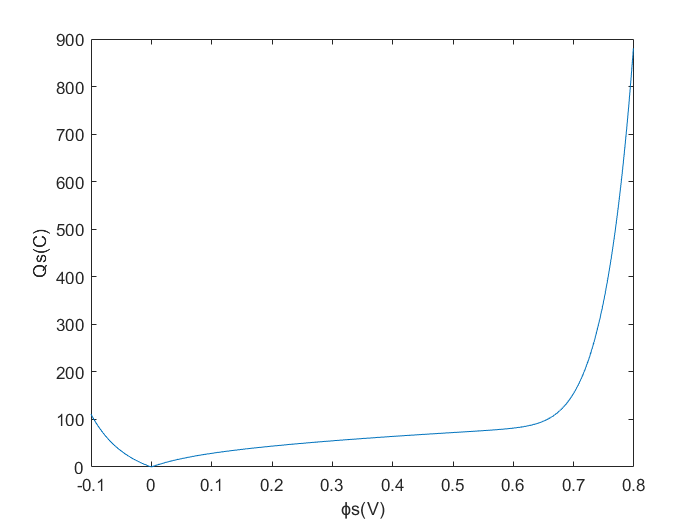

plot(phi(1:9e2),Qs1(1:9e2));
xlabel(char(981)+"s(V)");
ylabel('Qs(C)')